%% AE3 Orbital Mechanics Coursework 
% Submission deadline: Friday 18th March 2022 23:00 Europe/London
% create date: 13 Mar 2022

% creator: Cooper Chang Chien (01771697)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Question (i) 

clear all
close all
clc

% define physical constants

R_E = 6378;          % Earth radius (km)
mu_E = 398600;       % Earth gravitational parameter (km^3/s^2)
J2 = 0.00108263;     % Earth 2nd zonal harmonic coefficient


% define initial orbital elements (ECI)

a_0 = 6878;                  % semi-major axis (km)
e_0 = 1.3e-4;                % eccentricity
i_0 = deg2rad(53);           % inclined angle 
RAAN_0 = deg2rad(290.5);
w_0 = deg2rad(110);            
theta_0 = deg2rad(250);      % true anomaly

y_0 = [a_0 e_0 i_0 RAAN_0 w_0 theta_0];

h = sqrt(mu_E*a_0*(1-e_0^2));

A_w = [cos(w_0) sin(w_0) 0; -sin(w_0) cos(w_0) 0; 0 0 1];
A_i = [1 0 0; 0 cos(i_0) sin(i_0); 0 -sin(i_0) cos(i_0)];
A_RAAN = [cos(RAAN_0) sin(RAAN_0) 0; -sin(RAAN_0) cos(RAAN_0) 0; 0 0 1];

A = transpose(A_w*A_i*A_RAAN);

i_e = [1;0;0];
i_p = [0;1;0];

r0_p = (h^2/(mu_E*(1+e_0*cos(theta_0))))*(cos(theta_0)*i_e + sin(theta_0)*i_p);
v0_p = (mu_E/h)*(-sin(theta_0)*i_e + (e_0+cos(theta_0))*i_p);

r0_ECI = A*r0_p;
v0_ECI = A*v0_p;

sent1 = ['The Initial Position is ', '(',num2str(r0_ECI(1)),' ',num2str(r0_ECI(2)),' ',num2str(r0_ECI(3)),')'];
disp(sent1)

The Initial Position is (2408.8334 -6442.7177 9.0949e-13)



sent2 = ['The Initial Velocity is ', '(',num2str(v0_ECI(1)),' ',num2str(v0_ECI(2)),' ',num2str(v0_ECI(3)),')'];
disp(sent2)

The Initial Velocity is (4.2908 1.6052 6.0795)


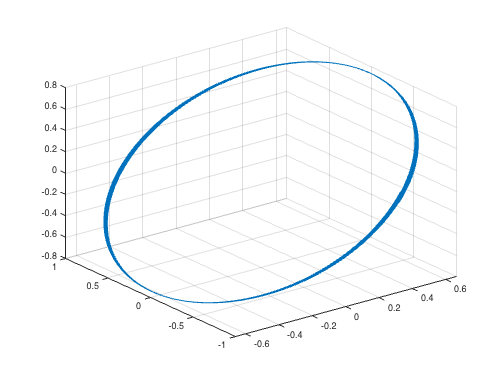


% undimensionalise
DU = norm(r0_ECI);
TU = sqrt(DU^3/mu_E);

r0 = r0_ECI/DU;
v0 = v0_ECI/(DU/TU);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% Question (ii) 

% define orbital period
% undimensionlise with TU
T_0 = 2*pi*sqrt(a_0^3/mu_E)/TU;
tspan = [0 10*T_0];

x0 = [r0' v0'];

tol = odeset('RelTol',1e-8,'AbsTol',1e-8);
[t,x] = ode45(@EoM,tspan,x0,tol);

%[t,x] = ode45('EoM',tspan,x0,'RelTol',1e-8,'AbsTol',1e-8);

r_0 = [x(:,1), x(:,2), x(:,3)];
v_0 = [x(:,4), x(:,5), x(:,6)];


% Plot Orbit trajectory
figure
plot3(x(:,1), x(:,2), x(:,3))
grid on
hold on

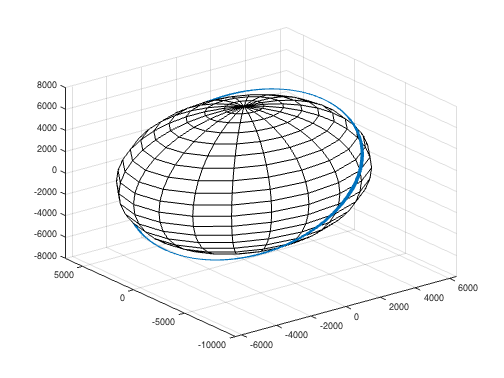



% Plot Orbit around earth
figure
plot3(x(:,1)*DU, x(:,2)*DU, x(:,3)*DU)
grid on
hold on
% Make unit sphere
[x1,y1,z1] = sphere;
% Scale to desire radius.
radius = R_E;
x2 = x1 * radius;
y2 = y1 * radius;
z2 = z1 * radius;
% Translate sphere to new location.
offset = R_E;
% Plot as surface.
earth = surf(x2,y2,z2);
set(earth, 'FaceColor', [1 1 1],'EdgeColor',[0 0 0]);

%axis equal



%% Run for simulation
% for i = 1:length(t)
%     plot3(x(1:i,1), x(1:i,2), x(1:i,3))
%     grid on
%     drawnow
% end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% Question (iii) 

% multiple by DU and TU to dimensionlise it
r = r_0*DU;
v = v_0*(DU/TU);
t = t*TU/3600;

sent3 = ['The Final Position is ', '(',num2str(r(2885,1)),' ',num2str(r(2885,2)),' ',num2str(r(2885,3)),')'];
disp(sent3)

The Final Position is (2534.7541 -6358.263 675.9222)



sent4 = ['The Final Velocity is ', '(',num2str(v(2885,1)),' ',num2str(v(2885,2)),' ',num2str(v(2885,3)),')'];
disp(sent4)

The Final Velocity is (4.0549 2.2601 6.0331)



% Initialise vector
r_norm = zeros(length(t),1);
v_norm = zeros(length(t),1);
a = zeros(length(t),1);
h = zeros(length(t),3);
h_norm = zeros(length(t),1);
e = zeros(length(t),3);
e_norm = zeros(length(t),1);
N = zeros(length(t),3);
N_norm = zeros(length(t),1);
in = zeros(length(t),1);
RAAN = zeros(length(t),1);
w = zeros(length(t),1);
theta = zeros(length(t),1);

%% calculate the orbital elements
for i = 1:length(t) 

    % calculate the angular momentum vector and norm
    % cross product rxv
    h(i,:) = cross(r(i,:),v(i,:));
    h_norm(i,1) = norm(h(i,:));

    % find the norm of position and velocity norm
    r_norm(i,1) = norm(r(i,:));
    v_norm(i,1) = norm(v(i,:));

    % calculate the eccentricity vector and norm
    e(i,:) = (1/mu_E)*(cross(v(i,:),h(i,:))-mu_E*(r(i,:)/r_norm(i,1)));
    e_norm(i,1) = norm(e(i,:));
    
    % calculate the semi-major axis
    energy = (v_norm(i,1)^2/2) - (mu_E/r_norm(i,1));
    a(i,1) = -mu_E/(2*energy);

    % calculate the inclination
    in(i,1) = rad2deg(acos(h(i,3)/h_norm(i,1)));

    %sinI = sqrt(h(i,1).^2 + h(i,2).^2)./h_norm(i,1).^2;
    %cosI = h(i,3)./sqrt(h_norm(i,1));
    %in(i,1) = atan2(sinI,cosI);

    % calculate the the location of node line
    i_z = [0 0 1]; 
    N(i,:) = cross(i_z,h(i,:));
    N_norm(i,1) = norm(N(i,:));

    % calculate RAAN
    if N(i,2)>0
        % positive plane,=
        RAAN(i,1) = 57.26*acos(N(i,1)/N_norm(i,1));
    else 
        % negative plane
        RAAN(i,1) = 360 - 57.26*acos(N(i,1)/N_norm(i,1));
    end

    % calculate argument of perigee
    if e(i,3)>0
        w(i,1) = 57.26*acos(dot(N(i,:),e(i,:))/(N_norm(i,1)*e_norm(i,1)));
    else
        w(i,1) = 360 - 57.26*acos(dot(N(i,:),e(i,:))/(N_norm(i,1)*e_norm(i,1)));
    end
    
    % calculate the true anomaly
    factor = dot(r(i,:),v(i,:));

    if factor<0
        theta(i,1) = 360 - rad2deg(acos(dot(r(i,:),e(i,:))/(r_norm(i,1)*e_norm(i,1))));
    else
        theta(i,1) = rad2deg(acos(dot(r(i,:),e(i,:))/(r_norm(i,1)*e_norm(i,1))));
    end

    % state vector
    y(i,:) = [a(i,1) e_norm(i,1) in(i,1) RAAN(i,1) w(i,1) theta(i,1)];

end

%% Averaging
% take the average of the osculating element
i_aver = sum(in)/length(t);
a_aver = sum(a)/length(t);
h_aver = sum(h_norm)/length(t);

% Incorporate equation from lecture slides (average Guass variation)
% For Right Ascension of Ascending Nodes (deg/hr)
n = sqrt(mu_E/a_aver^3);
RAAN_dot = -(3*n*J2*mu_E^2*R_E^2/(2*h_aver^4)) * cosd(i_aver) * 57.26 * 3600;

sent5 = ['The Right Ascension of Ascending Nodes averaged rate in deg/hr is ', num2str(RAAN_dot)];
disp(sent5)

The Right Ascension of Ascending Nodes averaged rate in deg/hr is -0.19243



% For Argument of perigee (deg/hr)
w_dot = (3*J2*mu_E^2*R_E^2*n)/(4*h_aver^4) * (5*cosd(i_aver)^2-1) * 57.26 * 3600;

sent5 = ['The Argument of Perigee averaged rate in deg/hr is ', num2str(w_dot)];
disp(sent5)

The Argument of Perigee averaged rate in deg/hr is 0.12984


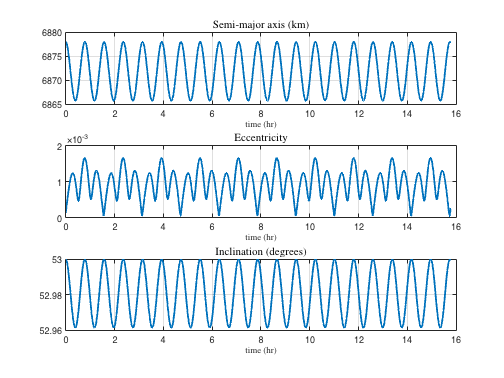


% Average by using graph
RAAN_dot1 = (RAAN(220,1)-RAAN(1,1))/(t(220,1)-t(1,1));
w_dot1 = (w(2880,1)-w(2306,1))/(t(2880,1)-t(2306,1));



%% plot the osculating orbital elements wrt to time

figure
subplot(3,1,1)
plot(t,a(:,1),'LineWidth',2)
title("Semi-major axis (km)",'Interpreter','latex','FontSize',12)
xlabel('time (hr)','Interpreter','latex','FontSize',10)
grid on

subplot(3,1,2)
plot(t,y(:,2),'LineWidth',2)
title("Eccentricity",'Interpreter','latex','FontSize',12)
xlabel('time (hr)','Interpreter','latex','FontSize',10)
grid on

subplot(3,1,3)
plot(t,y(:,3),'LineWidth',2)
title("Inclination (degrees)",'Interpreter','latex','FontSize',12)
xlabel('time (hr)','Interpreter','latex','FontSize',10)
grid on

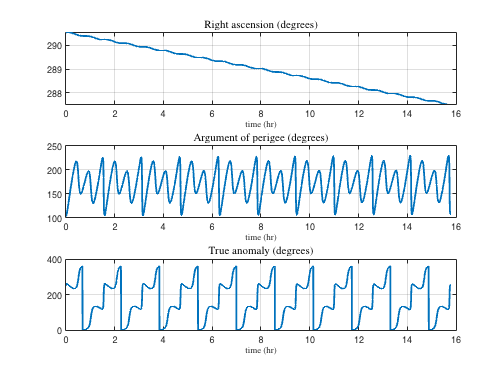


figure
grid on
subplot(3,1,1)
plot(t,y(:,4),'LineWidth',2)
title("Right ascension (degrees)",'Interpreter','latex','FontSize',12)
xlabel('time (hr)','Interpreter','latex','FontSize',10)
grid on

subplot(3,1,2)
plot(t,y(:,5),'LineWidth',2)
title("Argument of perigee (degrees)",'Interpreter','latex','FontSize',12)
xlabel('time (hr)','Interpreter','latex','FontSize',10)
grid on

subplot(3,1,3)
plot(t,y(:,6),'LineWidth',2)
title("True anomaly (degrees)",'Interpreter','latex','FontSize',12)
xlabel('time (hr)','Interpreter','latex','FontSize',10)
grid on